%% Question - 1
% Clear workspace and command window
clear; clc; close all;
% For reproducibility
rng(13); 

%% Given Data
N = 20;  % Number of Observations
R = 200; % Number of Realizations
beta = [0;3;5]; % True Beta

%% Initialize variables
beta_estimates = zeros(R, 3); % Store parameter estimates
loss = zeros(R, 1); % Store final cost
alpha = 0.01; % Learning rate
epochs = 1000; % Epochs or Number of Iterations

%% Perform Regression for R realizations
for r = 1:R
    % Generate Data
    X1 = randn(N, 1);
    X2 = randn(N, 1);
    E = randn(N, 1);
    y = beta(2)*X1 + beta(3)*X2 + E;
    X = [X1 X2];
    
    % Perform Regression
    [beta_hat, cost_history] = lts(X, y, alpha, epochs);
    beta_estimates(r, :) = beta_hat';
    loss(r) = cost_history(end);
end

%% Best beta across realizations
% Find the realization with the minimum sum of squared residuals
[min_ssr, best_parameter] = min(loss);
fprintf('Best realization Index: %d\n\n', best_parameter);

Best realization Index: 191



% Display best parameters
% Model parameter names
parameters = {'beta0', 'beta1', 'beta2'};
T = table(parameters', beta_estimates(best_parameter, :)', 'VariableNames', {'Parameters', 'Optimum'});
result_table = table(T,'VariableNames',{'Best_Parameters'});
disp(result_table);

       Best_Parameters   
    Parameters    Optimum
    _____________________

     'beta0'      0.10448
     'beta1'       3.0861
     'beta2'       4.2916



fprintf('Loss(For the optimal parameters): %.4f\n\n', min_ssr);

Loss(For the optimal parameters): 0.0128



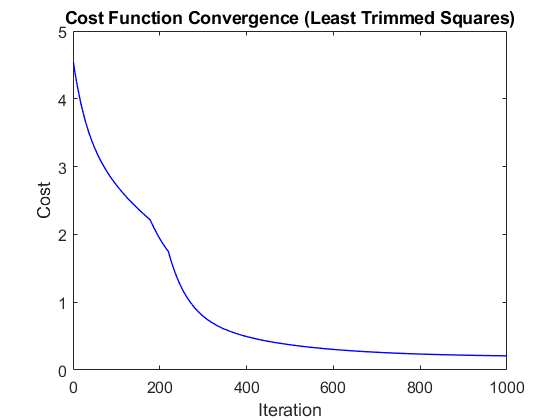

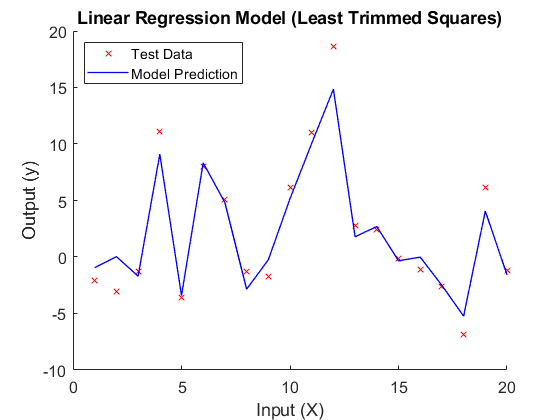

%% Model Testing
% Generate Test Data
rng(27); % Change reproducibility to generate new data
X1 = randn(N, 1);
X2 = randn(N, 1);
E = randn(N, 1);
y = beta(2)*X1 + beta(3)*X2 + E;
X = [X1 X2];
% Plot Results
plotresult(X, y, beta_estimates(best_parameter, :)', epochs, cost_history, "Least Trimmed Squares")

%% Calculate Metrics
[mse, rb, mad] = metrics(beta, beta_estimates);
% Display metrics
T = table(parameters', mse', rb', mad', 'VariableNames', {'Parameters', 'MSE', 'RB', 'MAD'});
result_table = table(T,'VariableNames',{'Model_Metrics'});
disp(result_table);

                   Model_Metrics               
    Parameters     MSE         RB         MAD  
    ___________________________________________

     'beta0'      0.4807    0.084793    0.37776
     'beta1'      4.4018    -0.98231    0.98231
     'beta2'      10.969     -1.7366     1.7366

